s1 = s1bsres2045bins76{:,:};
s2 = s2bsres2045bins54{:,:};
s2(:,1) = s2(:,1) - 1;

%dG = s1(end,2);
bound = -35.06;
bound_err = 0.68;
hydration = -25.18;
hydration_err = 0.76;
dG = bound - hydration;
dG_err = bound_err + hydration_err;

s2_raised = s2;
s2_raised(:,2) = s2(:,2) + dG;
s2_raised(:,3) = s2(:,3) + dG_err;
csvwrite('s2_raised.csv', s2_raised)

## S1 PMF

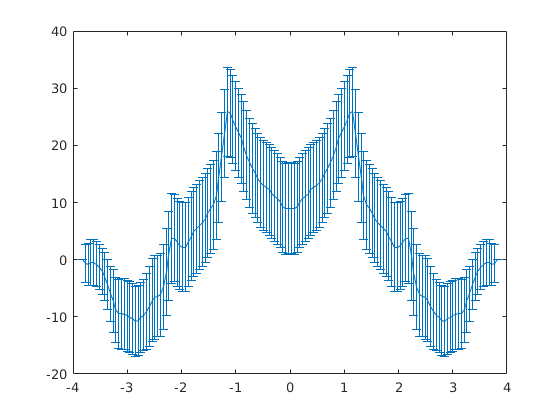

out = s1;
in = s1;
in(in(:,1) > 0, :) = [];
out(out(:,1) > 0, :) = [];
in(:,1) = abs(in(:,1));
in = flip(in);
S1 = [out;in];
errorbar(S1(:,1), S1(:,2), S1(:,3))

csvwrite('S1_PMF.csv', S1)

## S2 PMF

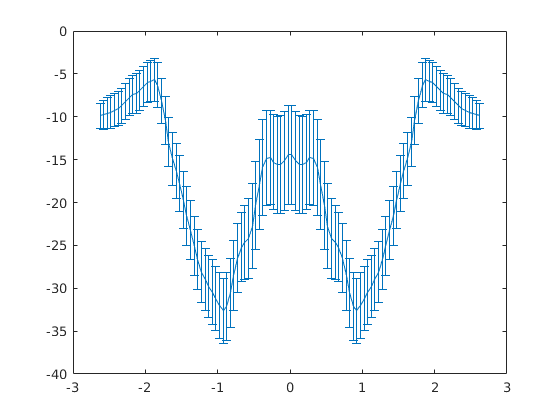

out = s2_raised;
in = s2_raised;
in(in(:,1) > 0, :) = [];
out(out(:,1) > 0, :) = [];
in(:,1) = abs(in(:,1));
in = flip(in);
S2 = [out;in];
errorbar(S2(:,1), S2(:,2), S2(:,3))

csvwrite('S2_PMF.csv', S2)